**Initialize Scenario**

startTime = datetime(2022,10,1,12,30,0);
stopTime = startTime + days(7);
sampleTime = 30;
sc = satelliteScenario(startTime,stopTime,sampleTime);

**Create Geosynchronous Constellation**

The TLE file used contains all six (6) of the Advanced Extremely High Frequency (AEHF) military satellite communications (MILSATCOM) satellites in geosynchronous orbit. 

sats = satellite(sc, "orbitalData\TLE\GEOSYNC.tle");

**Initialize Camera Sensors for each Satellite Element**

for idx = 1:numel(sats)
    name = sats(idx).Name + " Camera";
    conicalSensor(sats(idx), "Name", name, "MaxViewAngle", 65);
end

cam = [sats.ConicalSensors];

**Define Field-of-View for each Camera**

% fov1 = fieldOfView(cam(1));
fov2 = fieldOfView(cam(2), "LineColor", 'r');
fov3 = fieldOfView(cam(3), "LineColor", 'g');
fov4 = fieldOfView(cam(4), "LineColor", 'b');
% fov5 = fieldOfView(cam(5));
% fov6 = fieldOfView(cam(6));

**Display Orbital Elements**

elements1 = orbitalElements(sats(1));
elements2 = orbitalElements(sats(2));
elements3 = orbitalElements(sats(3));
elements4 = orbitalElements(sats(4));
elements5 = orbitalElements(sats(5));
elements6 = orbitalElements(sats(6));

**Add UCCS as Ground Station**

% Latitude & Longitude acquired from Google Maps
name = "UCCS Campus";
lat = 38.8886569787;
long = -104.793021161;
gs = groundStation(sc,"Name",name,"Latitude",lat, ...
    "Longitude", long);

**Display Access Intervals**

for idx = 1:numel(cam)
    access(cam(idx), gs);
end

% Retrieve the access analysis objects
ac = [cam.Accesses];

% Properties of access analysis objects
ac(1);

for idx = 1:numel(ac)
    ac(idx).LineColor = 'g';
end

accessIntervals(ac);

**Visualize the Scenario**

v = satelliteScenarioViewer(sc, ShowDetails=true);
campos(v, 12, long, 8e7)

**Calculate Latency and Velocity**

% Calculate azimuth, elevation, and range from each satellite to the ground station.
[az,el,r] = aer(sats,gs);

% Calculate latency.
c = physconst("Lightspeed");
latency = r/c;

**Calculate Velocity of each Satellite in NED Frame**

% Physically, this is the ECEF velocity, represented in NED frame of the satellite. 
% Therefore, the relative velocity with respect to the ground station is also the same.
[~,satV] = states(sats,CoordinateFrame="geographic");

% Calculate the direction of the ground station with respect to each
% satellite in its respective NED frame. satV is a 3-dimensional array,
% wherein the first dimension represents the cartesian component, second
% dimension represents the time sample, and third dimension represents the
% satellite. Therefore, compute the direction also as a 3-dimensional
% array, wherein the first dimension has a size of 1, the second dimension
% represents the time sample, and the third dimension corresponds to the
% satellite. To do this, az and el must also be re-formatted such that the
% first dimension, which represents the satellite becomes the third
% dimension. You can use permute to re-format the arrays as described.
dir = cat(1,permute(cosd(el).*cosd(az),[3 2 1]), ...
  permute(cosd(el).*sind(az),[3 2 1]), ...
  permute(-sind(el),[3 2 1]));

% Calculate the velocity along the line between the ground station and each
% satellite. This velocity determines the doppler frequency corresponding
% to each satellite. Re-format this velocity such that the first dimension
% corresponds to the satellite.
dopV = permute(dot(satV,dir),[3 2 1]);
ac = access(sats,gs);
[acStatus,time] = accessStatus(ac);

% Set the latency and doppler velocity to NaN whenever access status is
% false because these quantities are irrelevant when there is no access.
latency(~acStatus) = NaN;
dopV(~acStatus) = NaN;

**Plot Latency Corresponding to Sat-1**

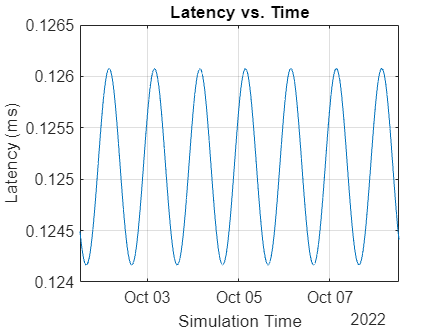

plot(time,latency(2,:))
xlim([sc.StartTime sc.StopTime])
title("Latency vs. Time")
xlabel("Simulation Time")
ylabel("Latency (ms)")
grid on

**Plot the Velocity Corresponding to Sat-1**

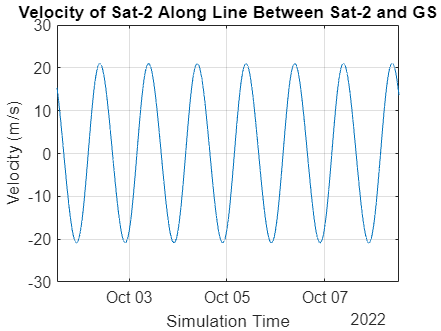

plot(time,dopV(2,:))
xlim([sc.StartTime sc.StopTime])
title("Velocity of Sat-2 Along Line Between Sat-2 and GS")
xlabel("Simulation Time")
ylabel("Velocity (m/s)")
grid on

**Calculate Doppler Frequency from Velocity**

fe = 5e9;                                % emitted frequency in Hz
fShift = (((c ./ (c-dopV)) * fe) - fe);  % doppler shift in Hz

**Plot the Doppler Shift Corresponding to the Sat-2**

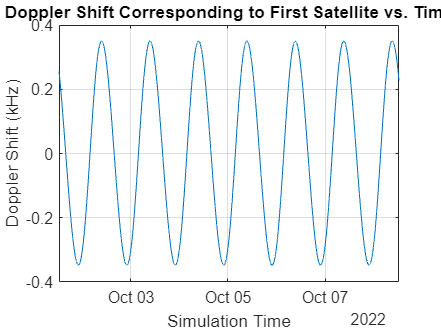

plot(time,fShift(2,:)/1e3)       % plot kHz
xlim([sc.StartTime sc.StopTime])
title("Doppler Shift Corresponding to First Satellite vs. Time")
xlabel("Simulation Time")
ylabel("Doppler Shift (kHz)")
grid on

**Calculate Rates of Change for Latency**

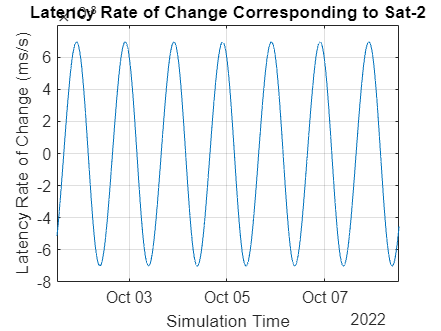

latencyRate = diff(latency,1,2)/sampleTime;
plot(time(1:end-1),latencyRate(2,:))                             % seconds/second
xlim([sc.StartTime time(end-1)])
title("Latency Rate of Change Corresponding to Sat-2")
xlabel("Simulation Time")
ylabel("Latency Rate of Change (ms/s)")
grid on

**Calculate Rates of Change for Doppler**

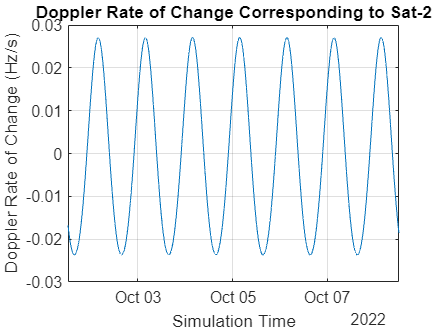

dopplerRate = (diff(fShift,1,2)/sampleTime);
plot(time(1:end-1),dopplerRate(2,:))
xlim([sc.StartTime time(end-1)])
title("Doppler Rate of Change Corresponding to Sat-2")
xlabel("Simulation Time")
ylabel("Doppler Rate of Change (Hz/s)")
grid on